clear offline_labeled_data_analysis
clc

load('../../../data/dynamic-1s-2s.mat')
rng(2022)

raw_tb = full_table

raw_tb = 225409×6 timetable
      Time          sEMG         MAV         RMS       Cue    Mean Frequency    Median Frequency
    _________    __________    ________    ________    ___    ______________    ________________

    0 sec              -2.5    0.024269    0.029415     0           0                  0        
    0.001 sec     -0.024414    0.024266    0.029408     0           0                  0        
    0.002 sec     -0.043945    0.024262    0.029401     0           0                  0        
    0.003 sec     -0.048828    0.024258    0.029395     0           0                  0        
    0.004 sec     -0.048828    0.024254    0.029388     0         

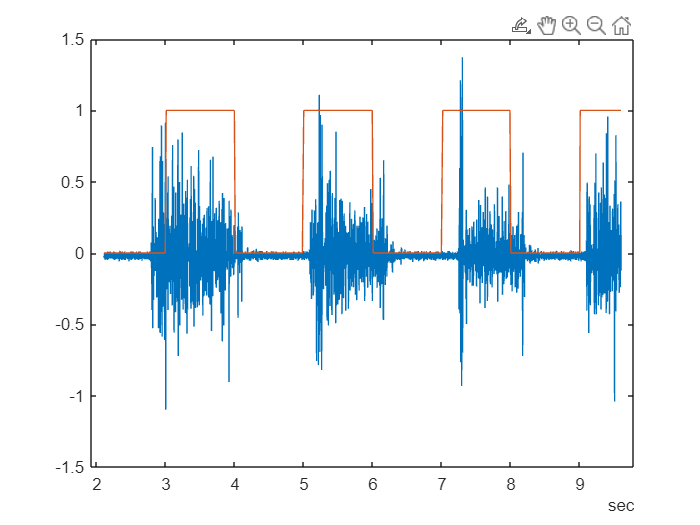

PLOT_DURATION = 7.5;
raw_fig = figure();
idx_start = randi(height(raw_tb), 1);
idx_end = idx_start + fs*PLOT_DURATION;
fig_tb = raw_tb(idx_start:idx_end, :);

xvals = fig_tb.Time;
plot(xvals, fig_tb.sEMG)
hold on
plot(xvals, fig_tb.Cue)
hold off

WINDOW_LEN_SEC = 0.1;
window_len_sam = fs*WINDOW_LEN_SEC

window_len_sam = 100

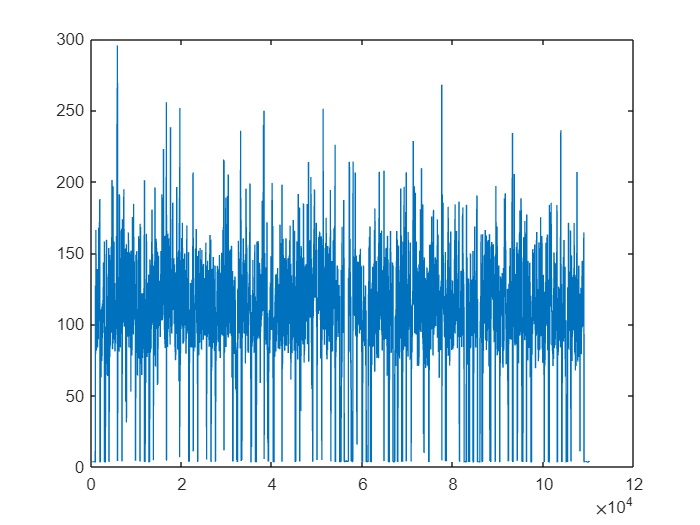

mdf = NaN(height(raw_tb),1);
j = 1;
for i=1:height(raw_tb)
    if i > window_len_sam && raw_tb.Cue(i)==1
        window_tb = raw_tb(i-window_len_sam:i, "sEMG");
        raw_sEMG = window_tb.sEMG;
        mdf(j) = medfreq(raw_sEMG, fs);
        j=j+1;
    end
end

plot(mdf)

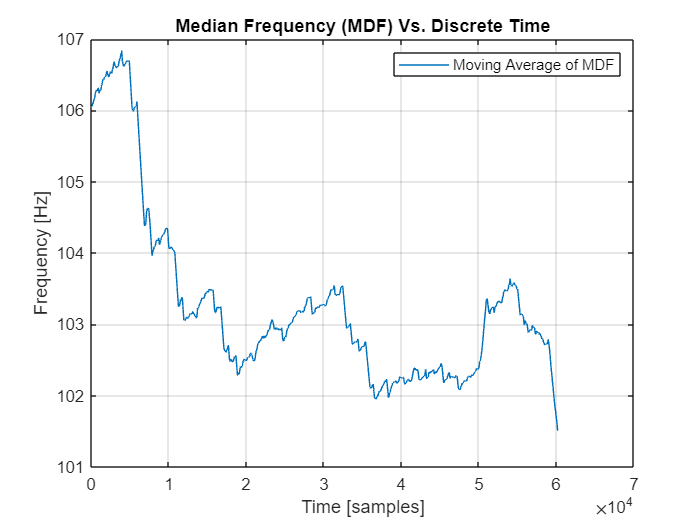

plot(movmean(mdf,100000))

xlim([0 70000])
ylim([101.00 107.00])
grid on
legend("Moving Average of MDF")
title("Median Frequency (MDF) Vs. Discrete Time")
xlabel("Time [samples]")
ylabel("Frequency [Hz]")